# WP4

Nota: prima di eseguire il codice assicurarsi di aver impostato come working directory di MATLAB la cartella "WP4".

clear all;  clc;

## Progettare un controllore feedback linearization con "metodo analitico"

Un primo controllore realizzato tramite la feedback linearization è stato fatto utilizzando il metodo "analitico".

Dapprima, si trova l'ingresso di controllo linearizzante per il sistema: 


$$ u(t) = \frac{1}{p_3x_1}\left[(p_1+x_2)^2x_1-(p_1+x_2)p_1g_e+p_2x_1x_2+p_3i_ex_1-v(t) \right]$$


Applicando l'ingresso linearizzante al sistema, si ottiene il seguente sistema equivalente: $\ddot{y} = v(t)$.

Si è scelto come ingresso di controllo equivalente: $v(t) = \ddot{y}_d + \alpha(\dot{y}-y_d)+\beta(y-y_d)$, dove $\alpha, \ \beta \in \mathbb{R}$. Per cui si ricava facilmente che: $(\ddot{y}_d - \ddot{y} ) - \alpha(\dot{y}-y_d)-\beta(y-y_d) = 0$. Questa è un equazione differenziale lineare omogenea del secondo ordine a coefficienti costanti e il polinomio caretteristico associato è $\lambda^2 -\alpha\lambda-\beta = 0$.

Per ottenere asintotica stabilità, avendo scelto come ingresso di controllo equivalente quello pocanzi descritto, è necessario che $\alpha <0 \ e  \ \beta<0 $. Per questo motivo si ricerceranno dei parametri $\alpha$ e $\beta$ che soddisfanno tale vincolo.

syms alpha beta
assume(alpha<0)
assume(beta<0)

A questo punto, si scelgono i parametri $\alpha$ e $\beta$ imponendo le prestazioni dinamiche desiderate. 

charpoly = [1 -alpha -beta];
ts = 6;
zita=1;
num = interp1([0.5 1/sqrt(2) 1], [8.0 5.9 5.8],zita);
omega_n = num/ts;
des_poly = [1 2*zita*omega_n omega_n^2];
sol = solve(charpoly == des_poly, [alpha, beta]);
alpha = double(sol.alpha);
beta = double(sol.beta);

Simulazione del sistema

simout = sim('v2_sim.slx');

Valutazione delle performance:

y = simout.y;
t = simout.t.Time;
u = simout.u;

y_stepinfo = stepinfo(y,t,y(end))

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 6.2411
     SettlingTime: 6.5063
      SettlingMin: 0.0451
      SettlingMax: 0.1013
        Overshoot: 124.5307
       Undershoot: 0
             Peak: 0.1013
         PeakTime: 0.2053


u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 5.4424
     SettlingTime: 11.0099
      SettlingMin: -2.3374
      SettlingMax: 78.8699
        Overshoot: 7.7694e+03
       Undershoot: 233.2180
             Peak: 78.8699
         PeakTime: 1.9110e-10


#### Plot dei grafici

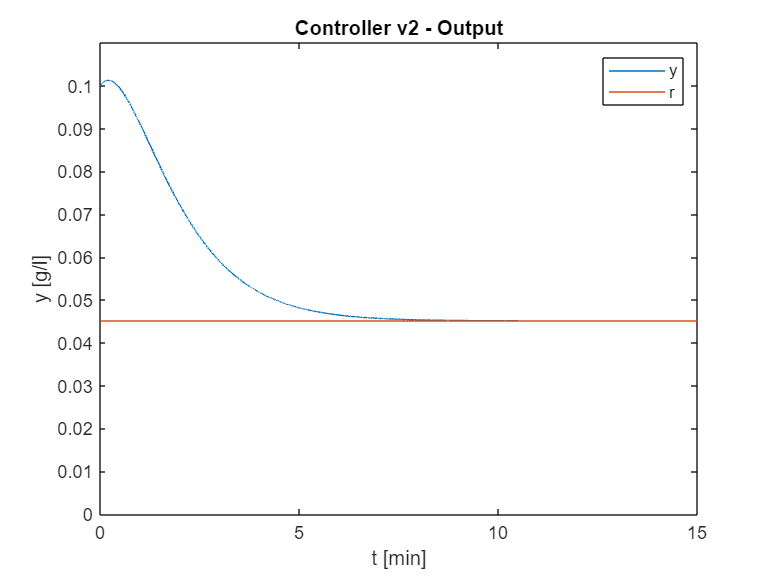

figure;
plot(t, y)
xlim([0,15])
title('Controller v2 - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

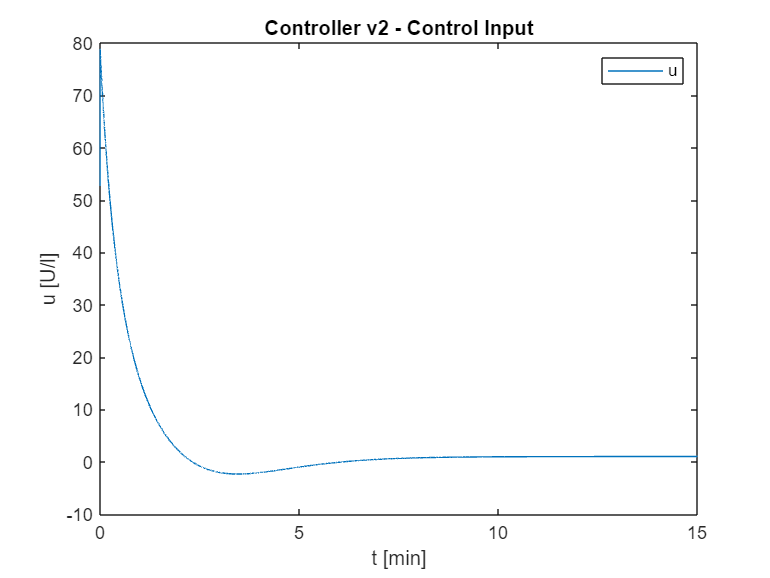

figure;
plot(t, u)
xlim([0,15])
title('Controller v2 - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

Il controllore realizzato ha delle performance soddisfacenti ma non è in grado di reiettare eventuali disturbi a gradino, poiché non è presente l'azione integrale.

## Progettare un controllore feedback linearization con "metodo analitico" e azione integrale

Si vuole realizzare un controllore sfruttando la stessa tecnica di controllo precedente usata, ma questa volta che permetta di reiettare eventuali disturbi a gradino. A questo scopo si introduce l'azione integrale.

clear all, clc;

Estendiamo lo stato del sistema linearizzato per aggiungere l'azione integrale.

La matrice dinamica a ciclo chiuso del sistema retroazionato è:

syms alpha beta gamma
A = [0 1 0; beta alpha gamma; -1 0 0];
char_poly_coeff = charpoly(A);

A questo punto cerchiamo di imporre il comportamento desiderato al sistema. Siccome il polinomio caratteristico è del terzo ordine, lo si scompone nel prodotto fra un polo ad alta frequenza e un polinomio del secondo ordine. Dopodiché, si sfrutta l'euristica per il quale il comportamento del sistema è approssimativamente uguale al sistema del secondo ordine, il quale viene opportunamente scelto.

syms s zita w_n p
desired_poly = (s^2 + 2*zita*w_n*s + w_n^2)*(s-p);
desired_poly_coeff = fliplr(coeffs(desired_poly, s));

sol = solve(char_poly_coeff==desired_poly_coeff,[alpha, beta, gamma],"ReturnConditions",true);

ts = 6;
zita=1;
num = interp1([0.5 1/sqrt(2) 1], [8.0 5.9 5.8],zita);
omega_n = num/ts;
p = -2;
alpha = double(subs(sol.alpha,{'zita','w_n','p'}, [zita, omega_n, p]));
beta = double(subs(sol.beta,{'zita','w_n','p'}, [zita, omega_n, p]));
gamma = double(subs(sol.gamma,{'zita','w_n','p'}, [zita, omega_n, p]));

Simulazione del sistema:

simout = sim('v2_sim_integral_action.slx');

Valutazione delle prestazioni:

y = simout.y;
t = simout.t.Time;
u = simout.u;
y_stepinfo = stepinfo(y,t,y(end))

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 6.8820
     SettlingTime: 7.1412
      SettlingMin: 0.0317
      SettlingMax: 0.1003
        Overshoot: 122.3677
       Undershoot: 0
             Peak: 0.1003
         PeakTime: 0.0450


u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 3.4483
     SettlingTime: 11.7359
      SettlingMin: -49.9799
      SettlingMax: 324.8020
        Overshoot: 3.2308e+04
       Undershoot: 4.9868e+03
             Peak: 324.8020
         PeakTime: 8.2397e-11


#### Plot dei grafici

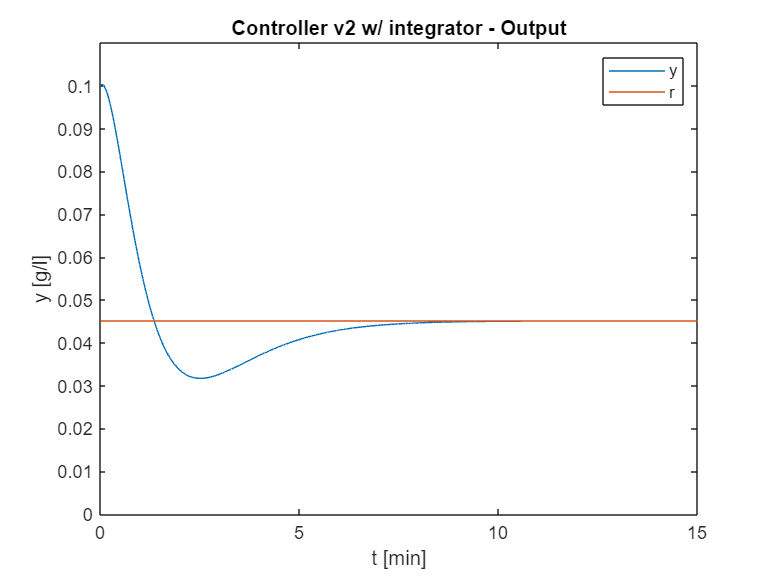

% Output
figure;
plot(t, y)
xlim([0,15])
title('Controller v2 w/ integrator - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

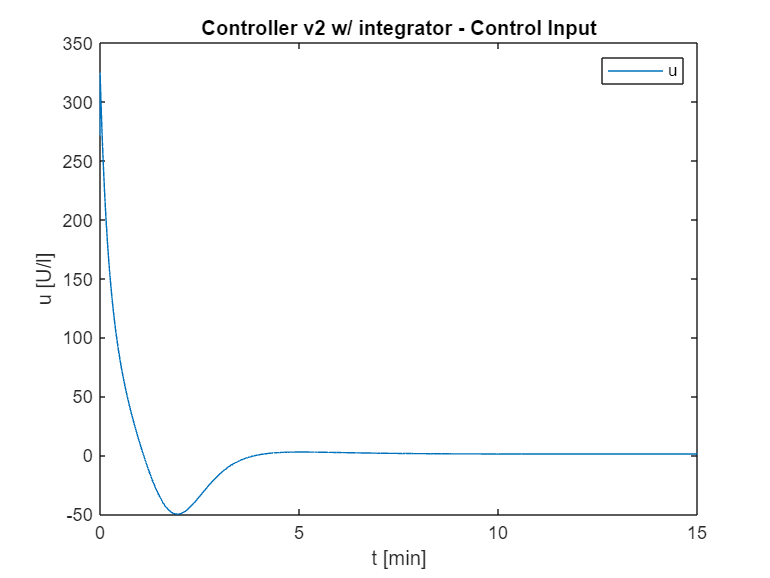

figure;
plot(t, u)
xlim([0,15])
title('Controller v2 w/ integrator - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

Le prestazioni non sono molto soddisfacenti soprattutto in termini dell'azione di controllo, la quale ha picchi positivi e negativi molto elevati. La taratura di questo controllore risulta ostica per via delle forti sottoelongazioni introdotte dall'azione integrale.

## Feedback linearization con PID

Infine, per provare comunque a reiettare i disturbi si è provato ad utilizzare come ingresso di controllo equivalente un controllore PID.

% La funzione di trasferimento del sistema da controllare è:
s = tf('s');
P = 1/s^2;
% rltool(P,1);

Per fare il tuning del controllore, si è utilizzata la tecnica del luogo delle radici. A questo scopo si è sfruttato il tool Control System Designer il quale ha facilitato la procedura di sintesi del controllore. 

La procudura di sintesi ha prodotto il seguente risultato:

C = 4.2975*(s+0.191)*(s+0.1311)/(s*(s+3.039));

Simulazione del sistema.

simout = sim('v2_sim_PID.slx');

Valutazione delle performance.

y = simout.y;
t = simout.t.Time;
u = simout.u;
y_stepinfo = stepinfo(y,t,y(end))

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 13.1316
     SettlingTime: 14.6732
      SettlingMin: 0.0372
      SettlingMax: 0.1004
        Overshoot: 122.5796
       Undershoot: 0
             Peak: 0.1004
         PeakTime: 0.0571


u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 3.0866
     SettlingTime: 19.5202
      SettlingMin: -49.5667
      SettlingMax: 243.0281
        Overshoot: 2.4149e+04
       Undershoot: 4.9456e+03
             Peak: 243.0281
         PeakTime: 0


undershoot = (min(y)-y(end))/y(end)

undershoot = -0.1747

#### Plot dei grafici

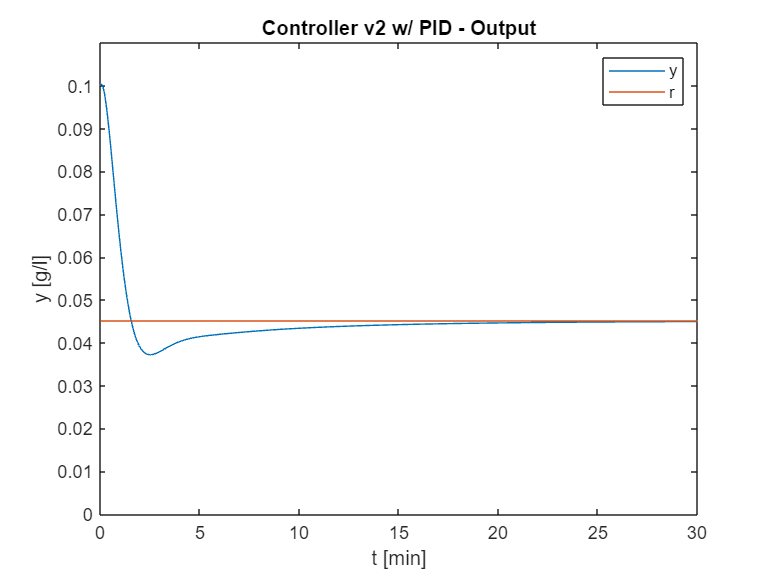

figure;
plot(t, y)
xlim([0,30])
title('Controller v2 w/ PID - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

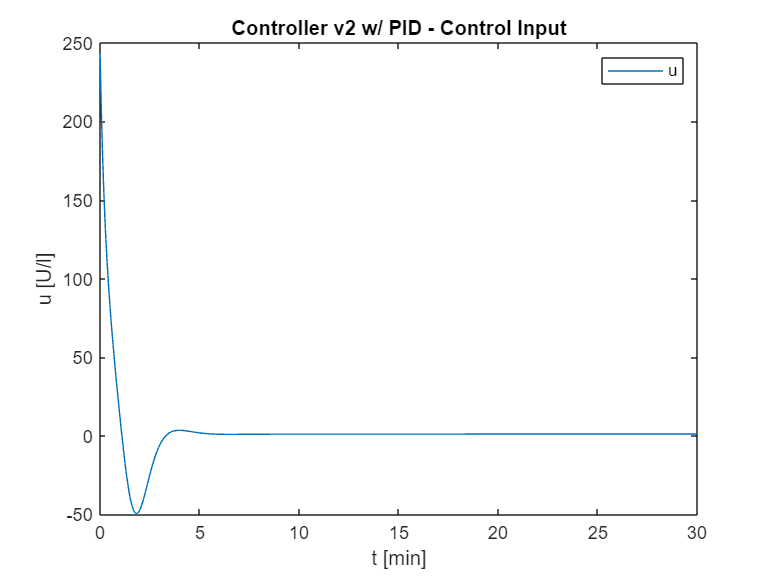

figure;
plot(t, u)
xlim([0,30])
title('Controller v2 w/ PID - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

I risultati in generale non sono troppo soddisfacenti: il sistema a ciclo chiuso manifesta picchi positivi e negativi importanti per quanto riguarda l'ingresso di controllo. Il tuning del controllo è stato realizzato allo scopo di contenere il più possibile questi picchi, cercando di preservare le performance dinamiche desiderate, ad esempio si vuole avere un buon tempo di assestamento, undershoot limitati e l'assenza di oscillazioni. Nel caso si volesse un controllore più performante si avrebbe un eccessivo aumento degli sforzi di controllo, mentre se si vuole ridurre lo sforzo di controllo si pagherebbe in termini di prestazioni dinamiche. Dunque, il controllore presentato rappresenta un trade-off fra questi due andamenti.